clear

% Initialize model
model

ans = '  t0 = sin(phi0+phi1+phi2)*-7.0E+1-sin(phi0*-1.0+phi1+phi2+phi3)*2.5E+1+sin(phi0-phi1*1.0)*5.5E+1-sin(phi0+phi1+phi2+phi3)*2.5E+1-sin(phi0+phi1)*5.5E+1-sin(phi0*-1.0+phi1+phi2)*7.0E+1;'

ans = '  t0 = cos(phi0+phi1+phi2)*7.0E+1-cos(phi0*-1.0+phi1+phi2+phi3)*2.5E+1-cos(phi0-phi1*1.0)*5.5E+1+cos(phi0+phi1+phi2+phi3)*2.5E+1+cos(phi0+phi1)*5.5E+1-cos(phi0*-1.0+phi1+phi2)*7.0E+1;'

ans = '  t0 = cos(phi1+phi2+phi3)*5.0E+1+cos(phi1+phi2)*1.4E+2+cos(phi1)*1.1E+2+1.2E+2;'

Elapsed time: 0.013221 s
Rotation: 49.6354      44.7705      60.5401      -14.021 deg
Error: 0.00022982


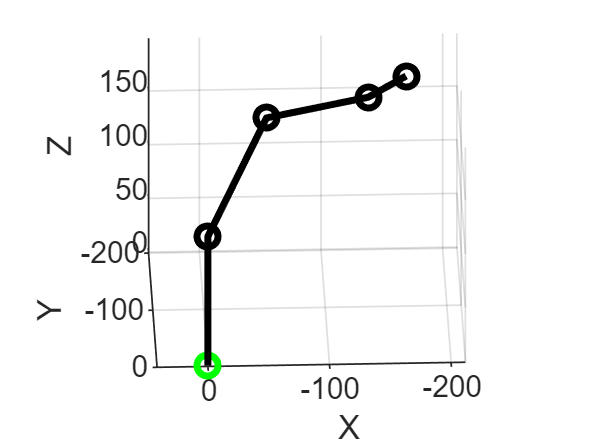


% Rotation constraints
phi_min = [-80, -50, -15, -15];
phi_max = [80, 50, 100, 90];

% Example Simulation
pos = [-170, -200, 160];
phi_0 = [0, 0, 0, 0];
simulate_ik(pos, phi_0, phi_min, phi_max, pos_fun, A0, A1, A2, A3);

Elapsed time: 0.0031285 s
Rotation: 26.565       53.884      81.1351 -0.000338227 deg
Error: 0.62349


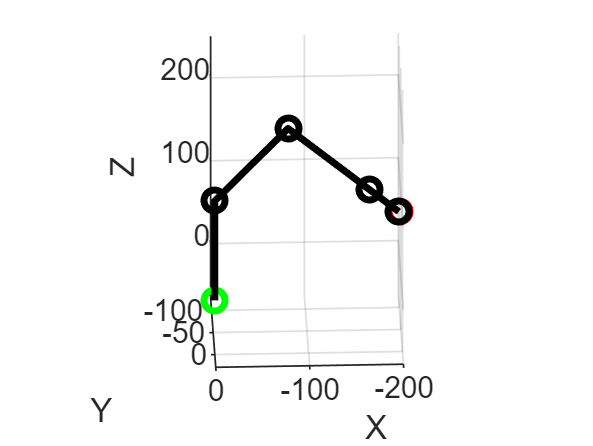


% Example Simulation
pos = [-200, -100, 50];
phi_0 = [0, 0, 0, 0];
simulate_ik(pos, phi_0, phi_min, phi_max, pos_fun, A0, A1, A2, A3);

Elapsed time: 0.0073717 s
Rotation: 45.0004      61.5651     0.210401   0.00174118 deg
Error: 502.7459


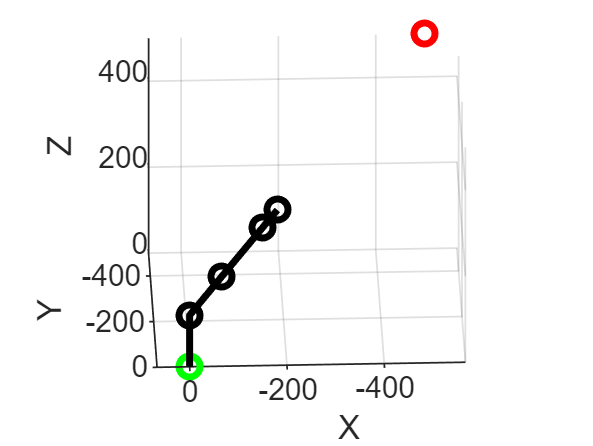


% Example Simulation
pos = [-500, -500, 500];
phi_0 = [0, 0, 0, 0];
simulate_ik(pos, phi_0, phi_min, phi_max, pos_fun, A0, A1, A2, A3);

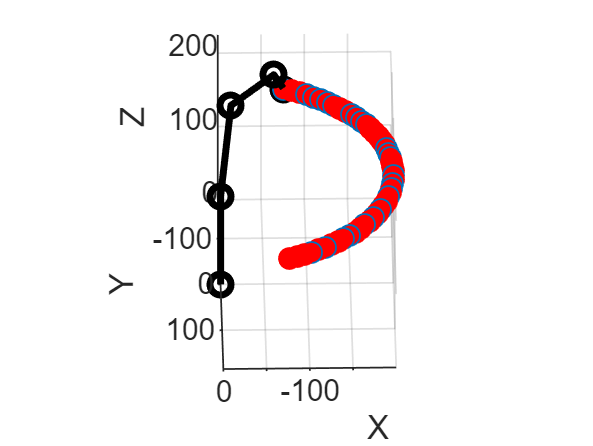


%Trajectory
trajectory(pos, phi_0, phi_min, phi_max, pos_fun, A0, A1, A2, A3);

Elapsed time is 66.139478 seconds.


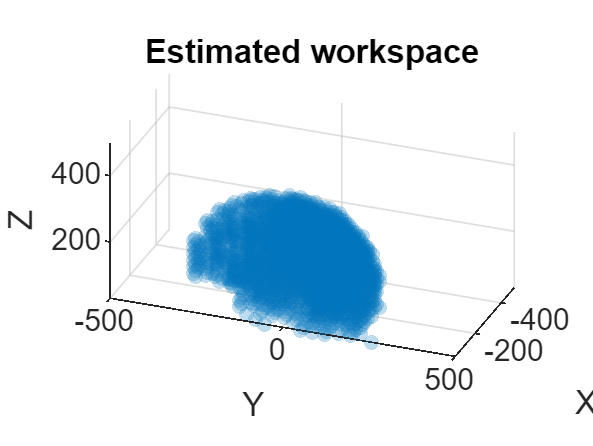


%Workspace
phi_0 = [0, 0, 0, 0];

workspace(pos, phi_0, phi_min, phi_max, pos_fun);